# Praktikum 3 - Shift 1 Selasa

`28 September 2021`

`Nama : Carolina Sinaga`

`NIM  : 10119050`

## **Nomor 1**

Sebutkan dan jelaskan keuntungan dari menyelesaikan SPL menggunakan metode dekomposisi $LU$ dibandingkan dengan metode Gauss-Seidel !

#### Jawaban :

- lebih efisien: Eliminasi Gauss-Seide menggunakan matriks augmented A(a,b) jadi b harus diketahui. Sementara itu, dekomposisi LU hanya menggunakan matriks A, jadi setelah faktorisasi selesai, dapat diterapkan ke vektor b apapun

- lebih cepat: dekomposisi LU memudahkan kita untukmenyelesaikan beberapa set persamaan dengan matriks koefisien yang sama tetapi sisi kanan yang berbeda dibandingkan eliminasi gauss-seide yang tidak bisa dengan sisi kanan yang berbeda-beda. 

## **Nomor 2**

Matriks Walsh (atau Matriks Hadamard terurut-alami) adalah sebuah keluarga matriks berukuran $2^n \times 2^n$ yang digunakan untuk menghitung *Walsh-Hadamard Transform, *sebuah prosedur varian dari *Discrete Fourier Transform,* yang mempunyai banyak kegunaan dalam *signal processing *dan *quantum computing.*

Matriks ini didefinisikan secara rekursif sebagai berikut:

#### 
$$W_1 =\left\lbrack \begin{array}{cc}
1 & 1\\
1 & -1
\end{array}\right\rbrack$$


#### 
$$W_m =\left\lbrack \begin{array}{cc}
W_{m-1}  & W_{m-1} \\
W_{m-1}  & -W_{m-1} 
\end{array}\right\rbrack ,m\ge 2$$


### 2A

Buatlah sebuah fungsi  `genWalshMatrix.m` yang menerima input bilangan asli $n$ dan mengembalikan matriks Walsh $W_n$.

% Run section untuk memeriksa jawaban anda.
n = 4;
genWalshMatrix(n)

ans =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1    -1     1    -1     1    -1     1    -1     1    -1     1    -1     1    -1     1    -1
     1     1    -1    -1     1     1    -1    -1     1     1    -1    -1     1     1    -1    -1
     1    -1    -1     1     1    -1    -1     1     1    -1    -1     1     1    -1    -1     1
     1     1     1     1    -1    -1    -1    -1     1     1     1     1    -1    -1    -1    -1
     1    -1     1    -1    -1     1    -1     1     1    -1     1    -1    -1     1    -1     1
     1     1    -1    -1    -1    -1     1     1     1     1    -1    -1    -1    -1     1     1
     1    -1    -1     1    -1     1     1    -1     1    -1    -1     1    -1     1     1    -1
     1     1     1     1     1     1     1     1    -1    -1    -1    -1    -1    -1    -1    -1
     1    -1     1    -1     1    -1     1    -1    -1     1    -1     1    -1     1    -1     1


### 2B 

Buatlah sebuah fungsi `doolittleLUDecomp.m` yang menerima input sebuah matriks persegi $A$ dan mengembalikan matriks  $L$`, `$U$ sehingga $A = LU$

% Run section untuk memeriksa jawaban anda. (Eh bentar, ini bisa di-run ga?
% Kodenya terlihat mencurigakan...jadi silahkan periksa baik-baik dulu, lalu koreksi!)
n = 8;
A = genWalshMatrix(n);
[L,U] = doolittleLUDecomp(A)

L =      1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0   

U =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     0    -2     0    -2     0    -2     0    -2     0    -2     0    -2     0    -2     0    -2     0    -2     0    -2     0    -2     0    -2     0    -2     0    -2     0    -2     0    -2     0    -2     0    -2     0    -2     0    -2     0    -2     0    -2     0    -2     0    -2     0    -2
     0     0    -2    -2     0     0    -2    -2     0     0    -2    -2     0     0    -2    -2     0     0    -2    -2     0     0    -2    -2     0     0    -2    -2     0     0    -2    -2     0     0    -2    -2     0     0    -2    -2     0     0    -2    -2     0     0    -2    -2     0     0
     0     0     0     4     0     0     0     4     0     0     0     4     0     0     0   

L*U

ans =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1    -1     1    -1     1    -1     1    -1     1    -1     1    -1     1    -1     1    -1     1    -1     1    -1     1    -1     1    -1     1    -1     1    -1     1    -1     1    -1     1    -1     1    -1     1    -1     1    -1     1    -1     1    -1     1    -1     1    -1     1    -1
     1     1    -1    -1     1     1    -1    -1     1     1    -1    -1     1     1    -1    -1     1     1    -1    -1     1     1    -1    -1     1     1    -1    -1     1     1    -1    -1     1     1    -1    -1     1     1    -1    -1     1     1    -1    -1     1     1    -1    -1     1     1
     1    -1    -1     1     1    -1    -1     1     1    -1    -1     1     1    -1    -1 

### 2C

Hitunglah determinan dari $W_2$ menggunakan hasil dekomposisi Doolittle-nya. Apakah matriks ini invertibel?

% Tuliskan jawaban anda disini, dalam bentuk program dan komentar.
n = 2;
A = genWalshMatrix(n);  % W_2
% dengan fungsi dekomposisi doolittle, kita dapat mengetahui 
% matriks segitiga atas(U) dan matriks segitiga bawah(L) dari matriks A
% akibatnya determinan(A) = determinan(L) x determinan(U)
[L,U] = doolittleLUDecomp(A);

% akan dicari determinan matriks segitiga bawah (L)
% yaitu hasil perkalian koefisien-koefisien diagonalnya
detL = 1; % inisiasi determinan L
for i = 1:2^n
    detL = detL*L(i,i);
end

% akan dicari determinan matriks segitiga atas (U)
% yaitu hasil perkalian koefisien-koefisien diagonalnya
detU = 1; % inisiasi determinan U
for i = 1:2^n
    detU = detU*U(i,i);
end

% determinan(A) = determinan(L) x determinan(U)
detA = detL*detU;
disp("Determinan A");

Determinan A


disp(detA);

    16



% apakah matriks A invertible?
if detA==0
    disp("Matriks A tidak invertible");
else
    disp("Ya, Matriks A invertible");
end

Ya, Matriks A invertible


### 2D

Gunakan dekomposisi Doolittle untuk mencari solusi untuk $\vec{x}$ sehingga $W_2 \vec{x} =$$\left\lbrack \begin{array}{c}
1\\
\frac{1}{2}\\
\frac{1}{3}\\
\frac{1}{4}
\end{array}\right\rbrack \ldotp$ Buatlah sebuah fungsi `solveSPL.m` yang menerima input $A$ matriks koefisien dan $b$ vektor hasil, dan mengembalikan vektor $\vec{x}$solusi dari persamaan yang diberikan.

% Uncomment section ini, lalu lengkapi bagian kosong dari section ini dan jalankan.
A = genWalshMatrix(2);  % W_2
b = [1;0.5;1/3;1/4];
x = solveSPL(A,b)

x =     0.5208
    0.1458
    0.2292
    0.1042


## Soal Bonus

### 2E

(Bonus kecil) Coba plot matriks $L$ atau $U$ menggunakan fungsi `imshow(L) `atau `imshow(U),` dari dekomposisi LDU (yang dapat dilakukan di soal 2F) dari matriks Walsh orde ke-8. 

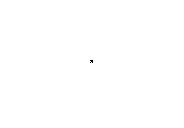

% Silahkan berikan kode jawaban Anda dibawah garis.
% ------------------------------------------------
imshow(L)

Apakah hasil plot mengingatkan Anda terhadap sebuah objek matematika/geometris tertentu? Sebutkan namanya/tipe objeknya.

% Silahkan berikan jawaban Anda.


### 2F

(Bonus Sedang) Buatlah sebuah fungsi `genDforLDU.m` yang menerima input matriks $L$, $U$ yang telah Anda bangun dengan dekomposisi Doolittle, dan mengembalikan matriks $D$ dan $U_{new}$ sehingga $D*U_{new}=U$  dengan diagonal $U_{new}$ semua bernilai 1 (sehingga kita peroleh matriks diagonal $D$ dan segitiga bawah unitrianguler $U_{new}$ sehingga $A = LDU_{new}$, ini kita sebut dekomposisi LDU). 

Coba amati dan bandingkan nilai-nilai dari matriks $L$ dan $U_{new}$`.` Apakah ada yang menarik/berhubungan?

% Silahkan berikan jawaban Anda.
